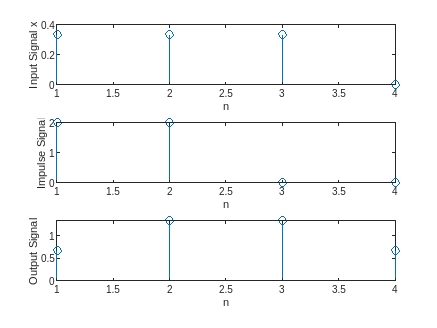

clc;clear;close all;

x=input('enter the input sequence values x(n)=');
h=input('enter the input sequence values h(n)=');

L1=length(x);
L2=length(h);
%length of linear convolution output
N=L1+L2-1;

x=[x zeros(1,N-L1)];
h=[h zeros(1,N-L2)];
X=fft(x);
H=fft(h);
Y=X.*H;
y=ifft(Y);

subplot(3,1,1);stem(x);xlabel('n'),ylabel('Input Signal x');
subplot(3,1,2);stem(h);xlabel('n'),ylabel('Impulse Signal');
subplot(3,1,3);stem(y);xlabel('n'),ylabel('Output Signal');